## Entrega 1

Calculando aproximación de área bajo la curva 

Prueba 1 **∫x^2dx**

% Define variables
N = 1e6; % Cantidad de intervalos
inf = -1; % Límite inferior
sup = 1; % Límite superior

rango = linspace(inf, sup, N);
salto = (sup - inf)/N;

% Define función 
f = @(x) x.^2;

% Aproximación de la integral
aproximation = sum(f(rango) * salto)

aproximation = 0.6667

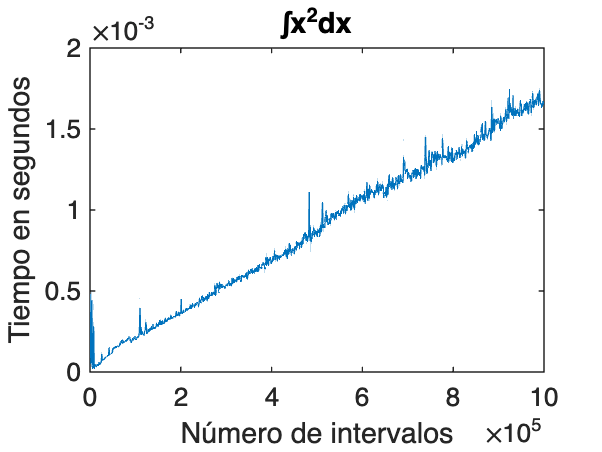


tiempo_ejecucion = zeros(size(1:1000:N));
res = zeros(size(1:1000:N));
indx = 1;
for t = 1:1000:N
    [tiempo_ejecucion(indx), res(indx)] = tiempo(f, t, inf, sup);
    indx = indx + 1;
end

plot(1:1000:N, tiempo_ejecucion)
title("∫x^2dx")
% Agregar etiquetas a los ejes X e Y
xlabel("Número de intervalos");
ylabel("Tiempo en segundos");

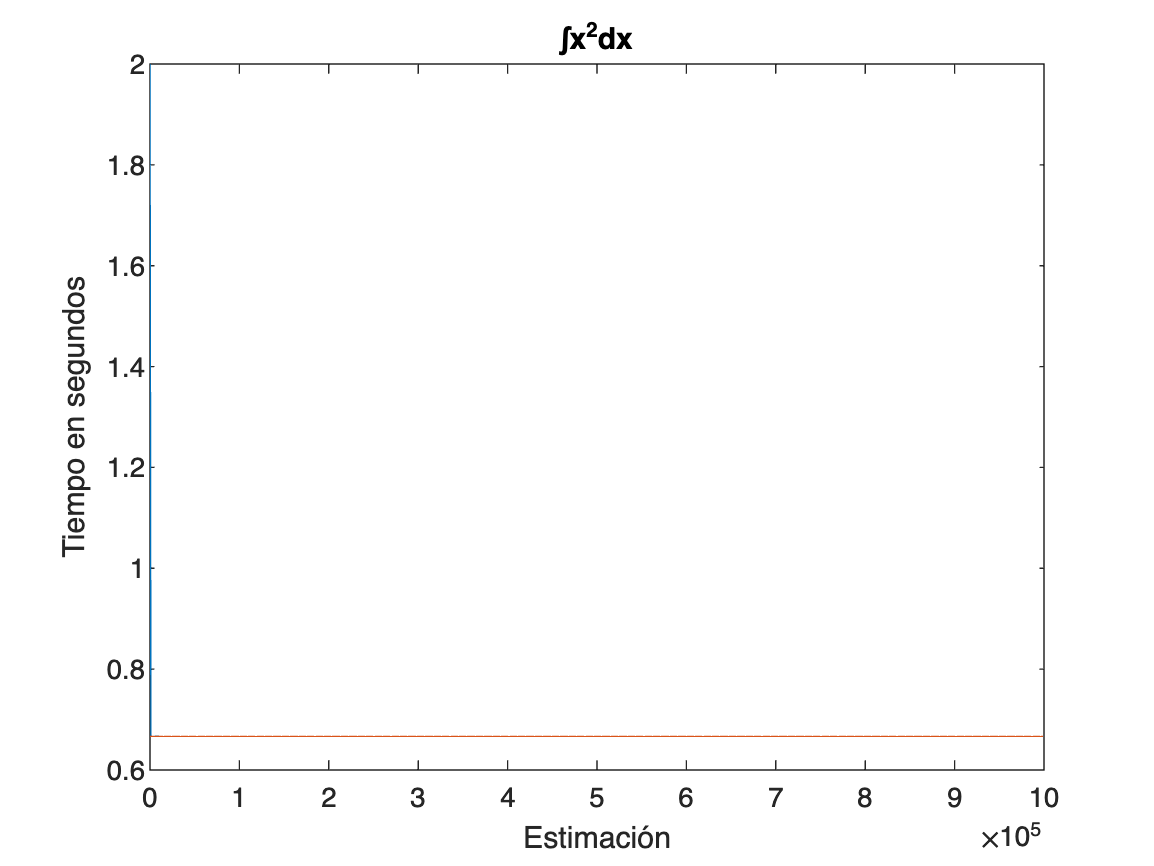


plot(1:1000:N, res)
hold on
plot(1:1000:N, zeros(size(1:1000:N)) + aproximation)
hold off
title("∫x^2dx")
% Agregar etiquetas a los ejes X e Y
xlabel("Estimación");
ylabel("Tiempo en segundos");

Prueba 2 **∫sin**θ**d**θ

% Define variables
N = 1e6; % Cantidad de intervalos
inf = 0; % Límite inferior
sup = 2*pi; % Límite superior

rango = linspace(inf, sup, N);
salto = (sup - inf)/N;

% Define función 
f = @(t) sin(t);

% Aproximación de la integral
aproximation = sum(f(rango) * salto)

aproximation = 1.1102e-16

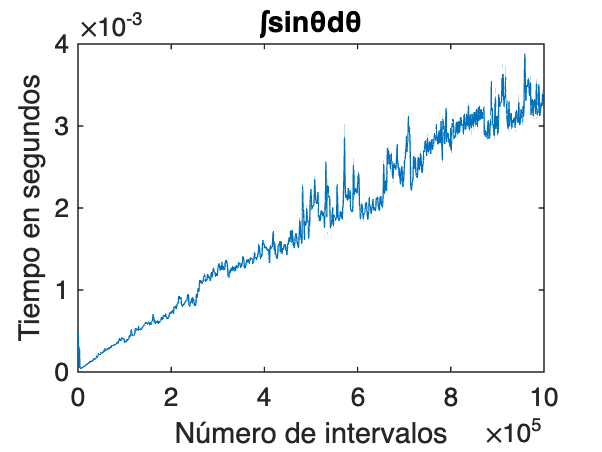


tiempo_ejecucion = zeros(size(1:1000:N));
res = zeros(size(1:1000:N));
indx = 1;
for t = 1:1000:N
    [tiempo_ejecucion(indx), res(indx)] = tiempo(f, t, inf, sup);
    indx = indx + 1;
end

plot(1:1000:N, tiempo_ejecucion)
title("∫sinθdθ")
% Agregar etiquetas a los ejes X e Y
xlabel("Número de intervalos");
ylabel("Tiempo en segundos");

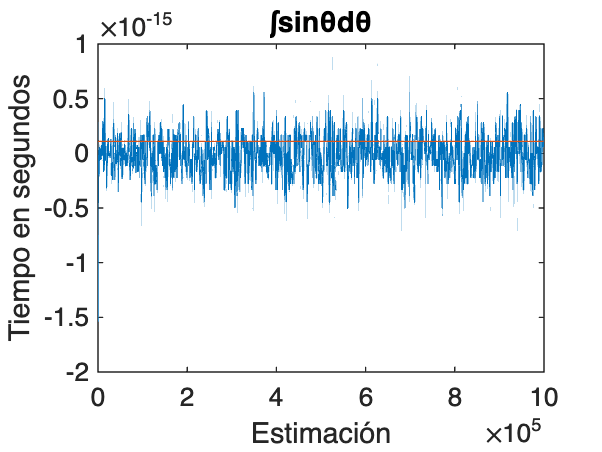


plot(1:1000:N, res)
hold on
plot(1:1000:N, zeros(size(1:1000:N)) + aproximation)
hold off
title("∫sinθdθ")
% Agregar etiquetas a los ejes X e Y
xlabel("Estimación");
ylabel("Tiempo en segundos");

Observamos que teniendo 1e6 intervalos genera un resultado aproximado al valor real. 

Considerando que una computadora realiza una acción cada en 1e-8 segundos, y que cada iteracion realiza tres acciones (evaluar en la función, multiplicar por el salto y sumar al resultado), cada una de ellas constante, podemos saber que la complejidad es líneal con respecto al número de intervalos de precisión.

Aunque la funcion potencia y la función trigonométrica tiene diferentes acciones, su forma más eficente, al menos en este contexto, es de complejidad constante. 

En le caso de la primera función, aunque es verdad que la operación x*x podría hacer crecer logaritmicamente la complejidad de la función con respecto a los límites de integración, los propios límites de la computación nos impiden que se vuelva relevante a gran escala.

En caso de la segunda función, aunque no conocemos la implementación de la función sin() en MATLB, podemos suponer que se basa en una serie de Taylor o en métodos de aproximación numérica para calcular el valor del seno. La complejidad de estas operaciones depende del número de términos de la serie de Taylor utilizados o de la precisión requerida para la  aproximación.

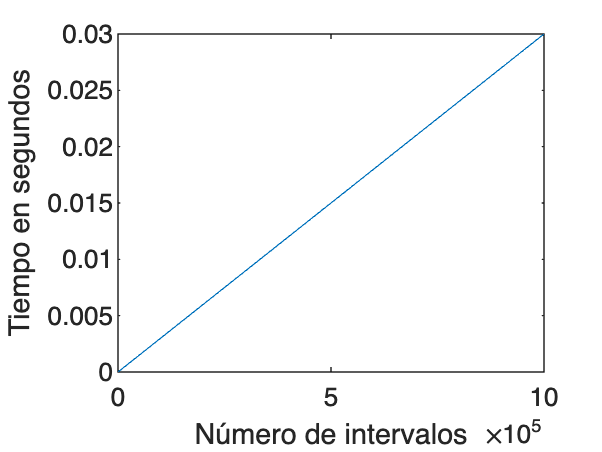

numero_de_intervalos = 1:1e6;
plot(numero_de_intervalos, 3 * 1e-8 * numero_de_intervalos)

% Agregar etiquetas a los ejes X e Y
xlabel("Número de intervalos");
ylabel("Tiempo en segundos");

## Campo Magnético

El siguiente código resulta en una gráfica de calor que representa la magnitud de los vectores resultantes sobre un plano paralelo al plano xy del campo magnetico de una cicuferencia situada en el plano xy con centro en (0, 0, 0).

Dar valos a las variables independientes

% Define variables
N_z = 15; % Precisión de la absisas
N_y = 15; % Precisión de la ordenadas
zmin = -3; % Límite inferior de las absisas
zmax = 3; % Límite superior de las absisas
ymin = -7; % Límite inferior de las ordenadas
ymax = 7; % Límite superior de las ordenadas
N_int = 100; % Precisión de la integral

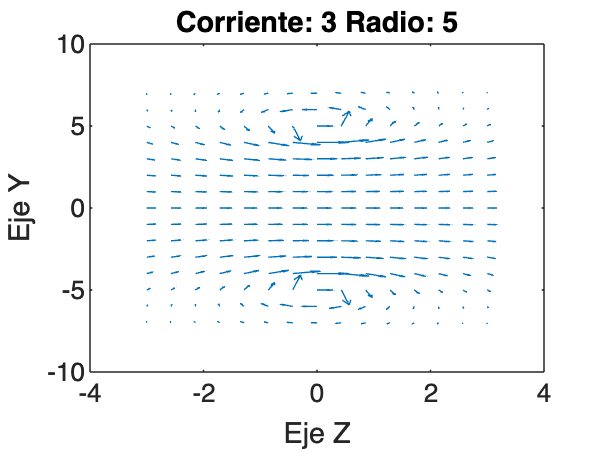

visualizeCampo(N_y, N_z, ymin, ymax, zmin, zmax, 3, 5, N_int)

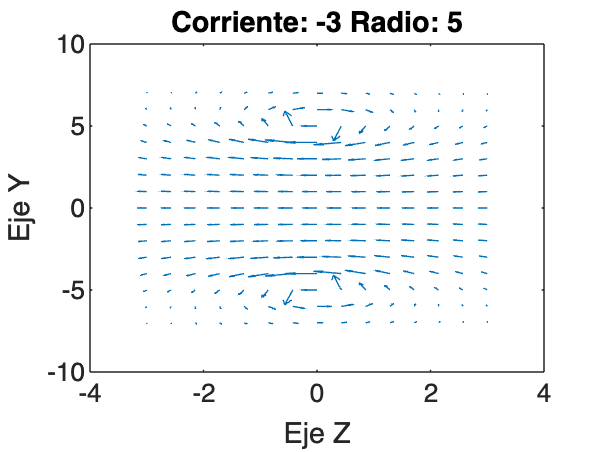

visualizeCampo(N_y, N_z, ymin, ymax, zmin, zmax, -3, 5, N_int)

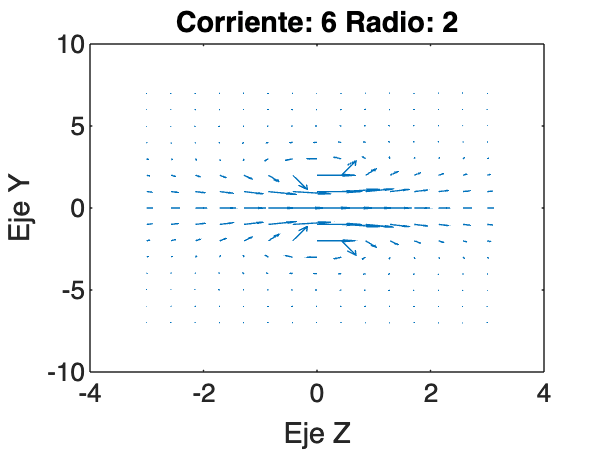

visualizeCampo(N_y, N_z, ymin, ymax, zmin, zmax, 6, 2, N_int)

function [ds] = vds(theta) % Calcular vector ds
    ds = [-sin(theta); cos(theta); zeros(size(theta))];
end

function [r] = vr(theta, R, x, y, z) % Calcular vector r
    r = [(x - R * cos(theta)); (y - R * sin(theta)); (zeros(size(theta)) + z)];
end

function [mr] = mr(theta, R, x, y, z) % Calcular magnitud de vector r
    mr = (x - R * cos(theta)).^2 + (y - R * sin(theta)).^2 + z^2;
end

function [B_i, B_j, B_k] = getCampoMagnetico(I, R, N_int, x, y, z)
    % Constante miu_0
    miu_0 = (4 * pi) * 1e-7;
    % Vector de intervalos de integración
    theta = linspace(0, 2 * pi, N_int);
    % Tamaño de cada intervalo de integración
    diff = 2 * pi / N_int;
    
    B = ((miu_0 * I * R) / (4 * pi)) * cross(vds(theta), vr(theta, R, x, y, z) ./ (mr(theta, R, x, y, z)).^(3/2)) * diff;
    
    % Sumar componentes del vector resultante
    B_i = sum(B(1, :));
    B_j = sum(B(2, :));
    B_k = sum(B(3, :));

end

function visualizeCampo(N_y, N_z, ymin, ymax, zmin, zmax, I, R, N_int)
    % Create grids
    z = linspace(zmin, zmax, N_z);
    y = linspace(ymin, ymax, N_y);
    [Z, Y] = meshgrid(z, y);
    
    [~, z_dim] = size(z);
    [~, y_dim] = size(y);

    B_k = zeros(z_dim, y_dim);
    B_j = zeros(z_dim, y_dim);
    B_i = zeros(z_dim, y_dim);
    
    % Calcular campo magnético para todo punto en el plano
    for i = 1:y_dim
        for j = 1:z_dim
            [B_i(i,j), B_j(i,j), B_k(i,j)] = (getCampoMagnetico(I, R, N_int, 0, Y(i, j), Z(i, j)));
        end
    end

    quiver(Z, Y, B_k, B_j);
    title("Corriente: " + string(I) + " Radio: " + string(R))
    xlabel("Eje Z");
    ylabel("Eje Y");

end
    
function [time, res] = tiempo(f, N_int, inf, sup)
    tic;
    rango = linspace(inf, sup, N_int);
    salto = (sup - inf)/N_int;
    res = sum(f(rango) * salto);
    time = toc;
end